# E10

#### HoG

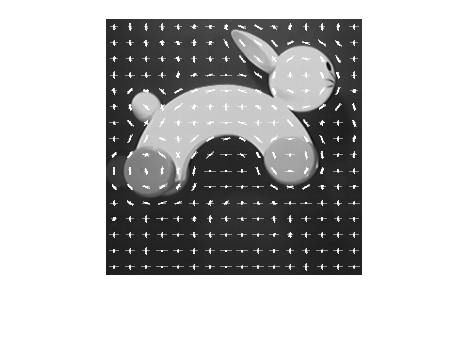

im = imread("rabbit.jpg");
im = imresize(im, [256 256]);
imshow(im)

[HoG, HoGVec] = extractHOGFeatures(im, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);
hold on
plot(HoGVec);
hold off

**Retall per HoG**

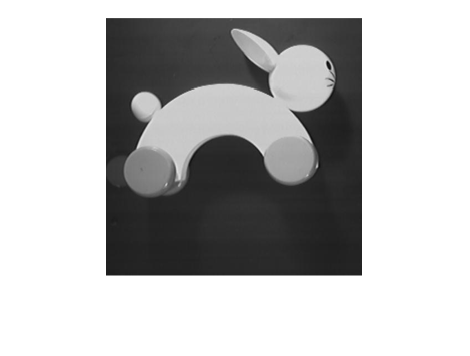

im = imread("rabbit.jpg");
im = imresize(im, [256 256]);
imshow(im)
[c, f] = getpts;

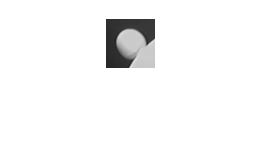

rect = [c-24,f-24,48,48];
Retall = imcrop(im, rect);
figure
imshow(Retall);

HoGR = extractHOGFeatures(Retall, 'CellSize', [16 16], 'BlockSize', [3 3], 'NumBins', 9);
FIG = reshape(HoG, [81,14*14])';
sim = zeros([14*14, 1]); % semblança
for i = 1:14*14
    sim(i) = sum(min(FIG(i, :), HoGR)); % semblanza per intersecció
end

[val, pos_block] = max(sim)

val = 6.4800

pos_block = 19

#### Exercici: dibuixar un rectangle en la posicio pos_block

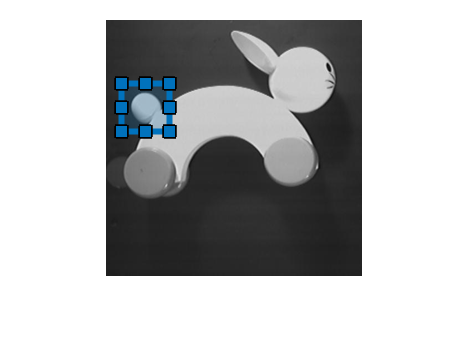

im = imread("rabbit.jpg");
im = imresize(im, [256 256]);
Dibuixar_Rectangle(im, pos_block);

**Histograma: emparellament d'imatges mitjançant histogrames**

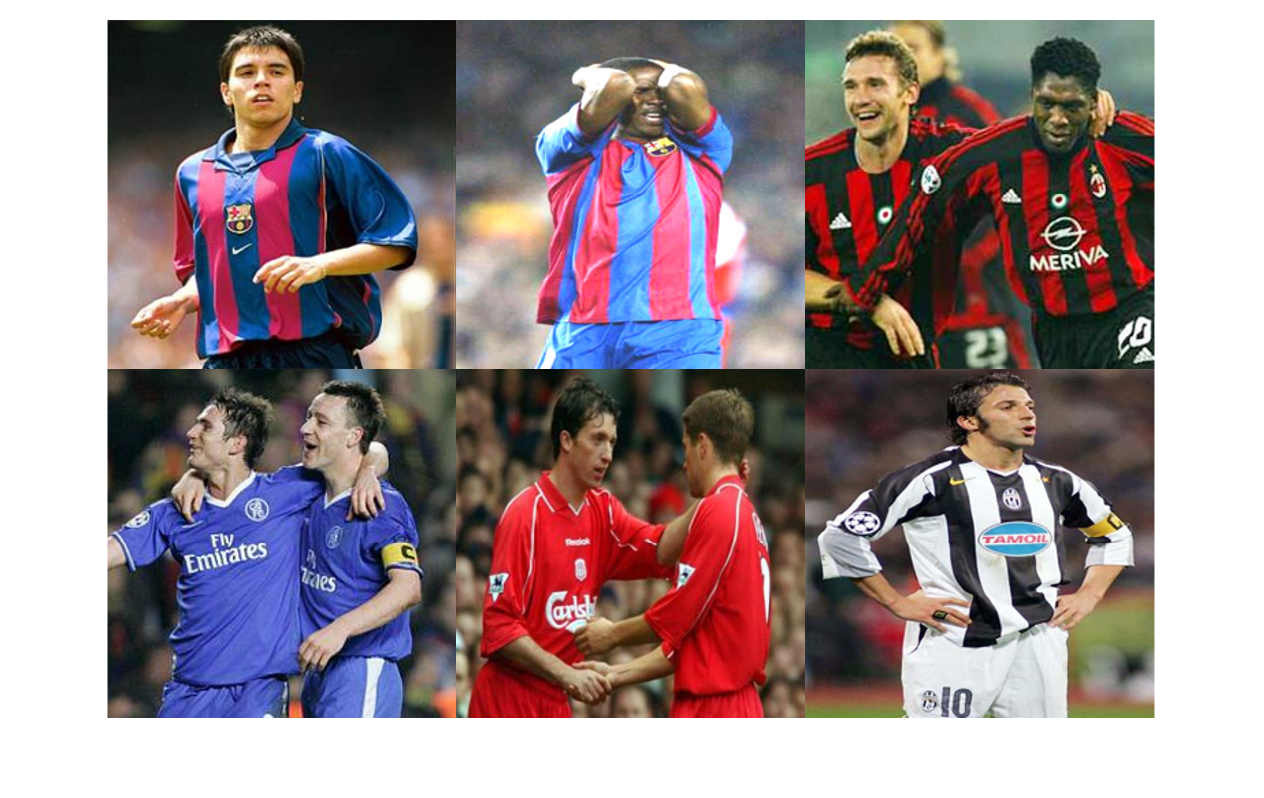

% 1r pas: llegir les imatges i retallar-les per tenir la mateixa mida
im = imread("team1.jpg");
im = imresize(im, [256 256]);
im1 = imread("team2.jpg");
im1 = imresize(im1, [256 256]);
im2 = imread("team5.jpg");
im2 = imresize(im2, [256 256]);
im3 = imread("team11.jpg");
im3 = imresize(im3, [256 256]);
im4 = imread("team12.jpg");
im4 = imresize(im4, [256 256]);
im5 = imread("team8.jpg");
im5 = imresize(im5, [256 256]);
montage({im,im1,im2,im3,im4,im5})

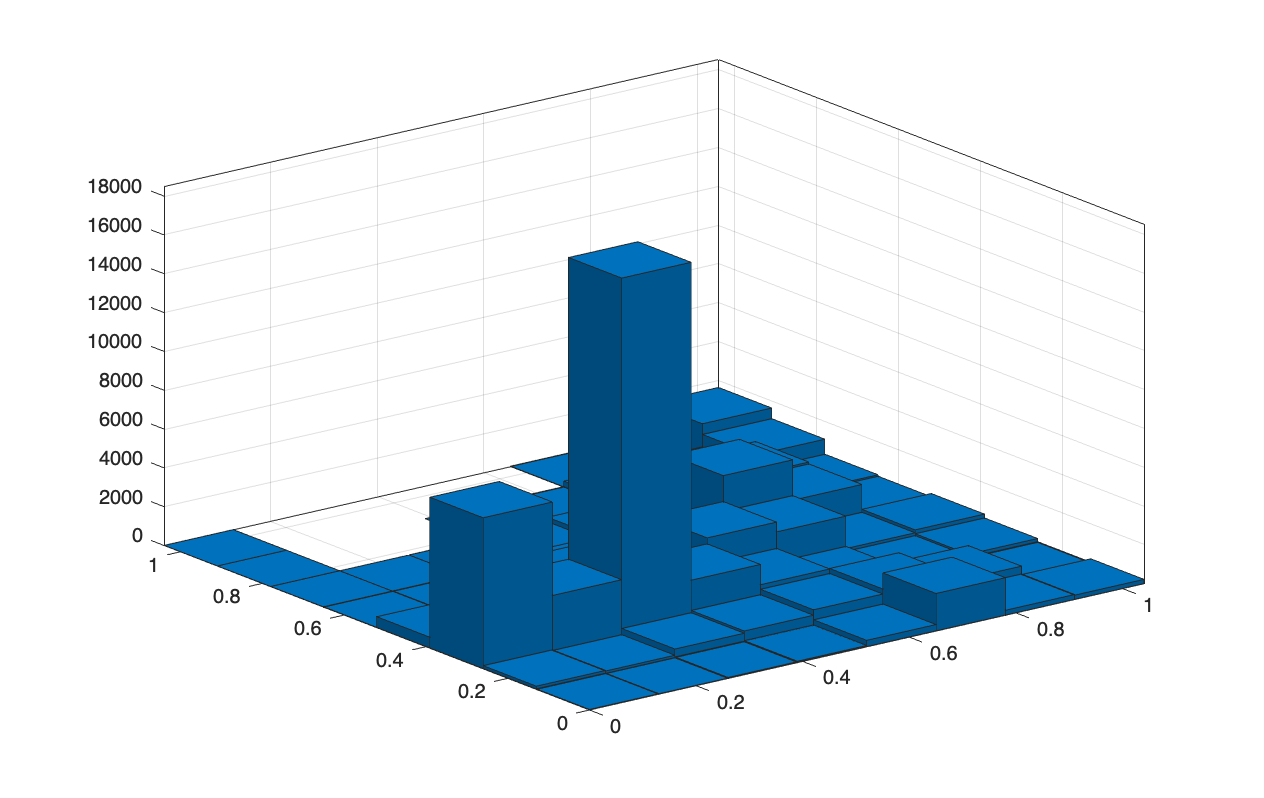

% 2n pas: calcular l'histograma de les imatges
h = Calcular_Histograma_rg(im).Values;

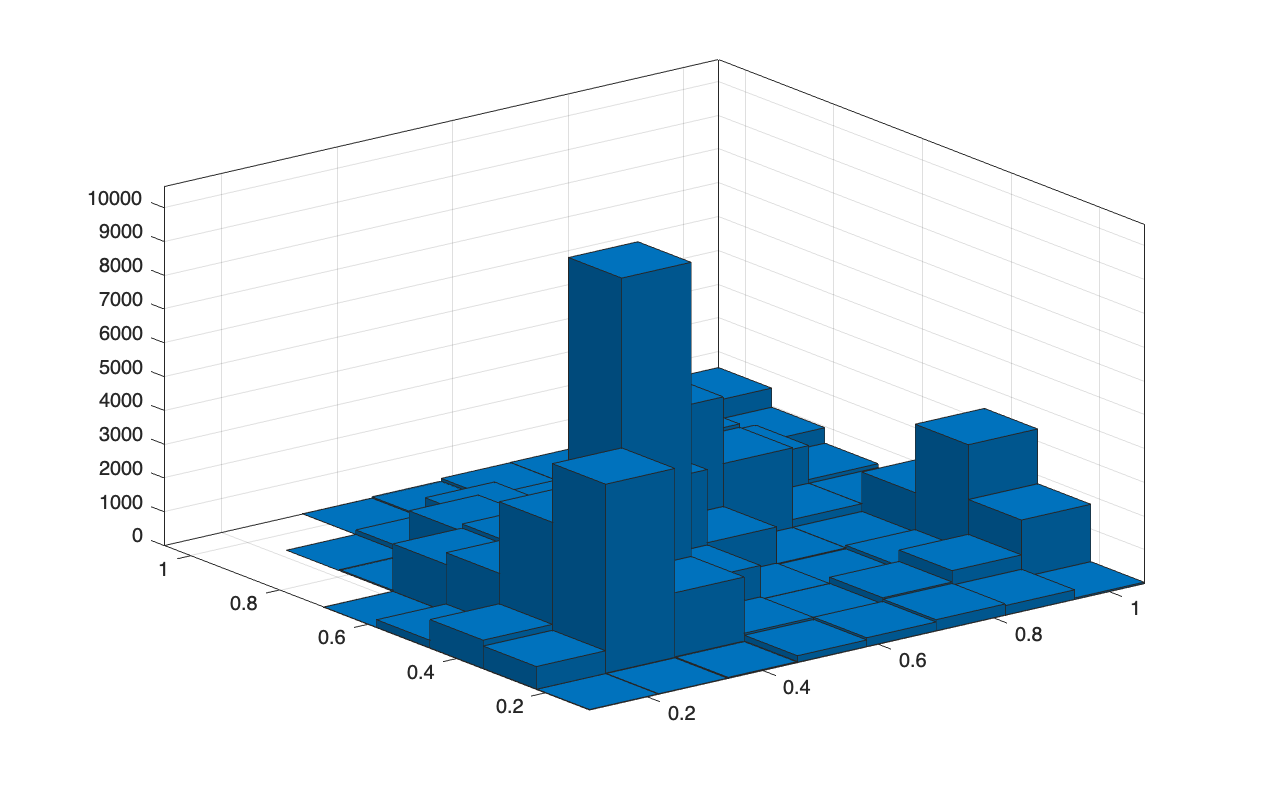

h = h./sum(h);
h1 = Calcular_Histograma_rg(im1).Values;

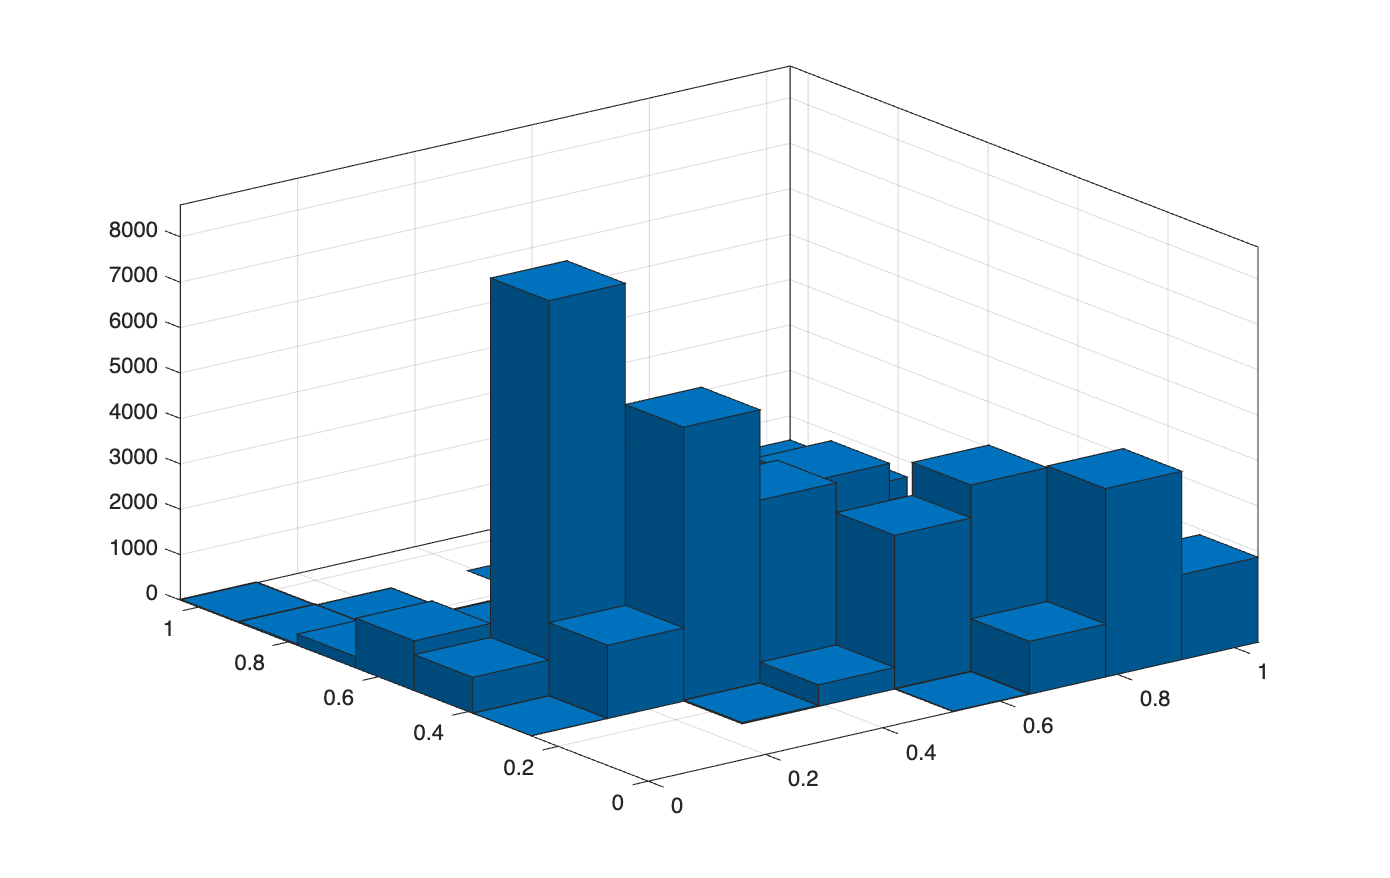

h1 = h1./sum(h1);
h2 = Calcular_Histograma_rg(im2).Values;

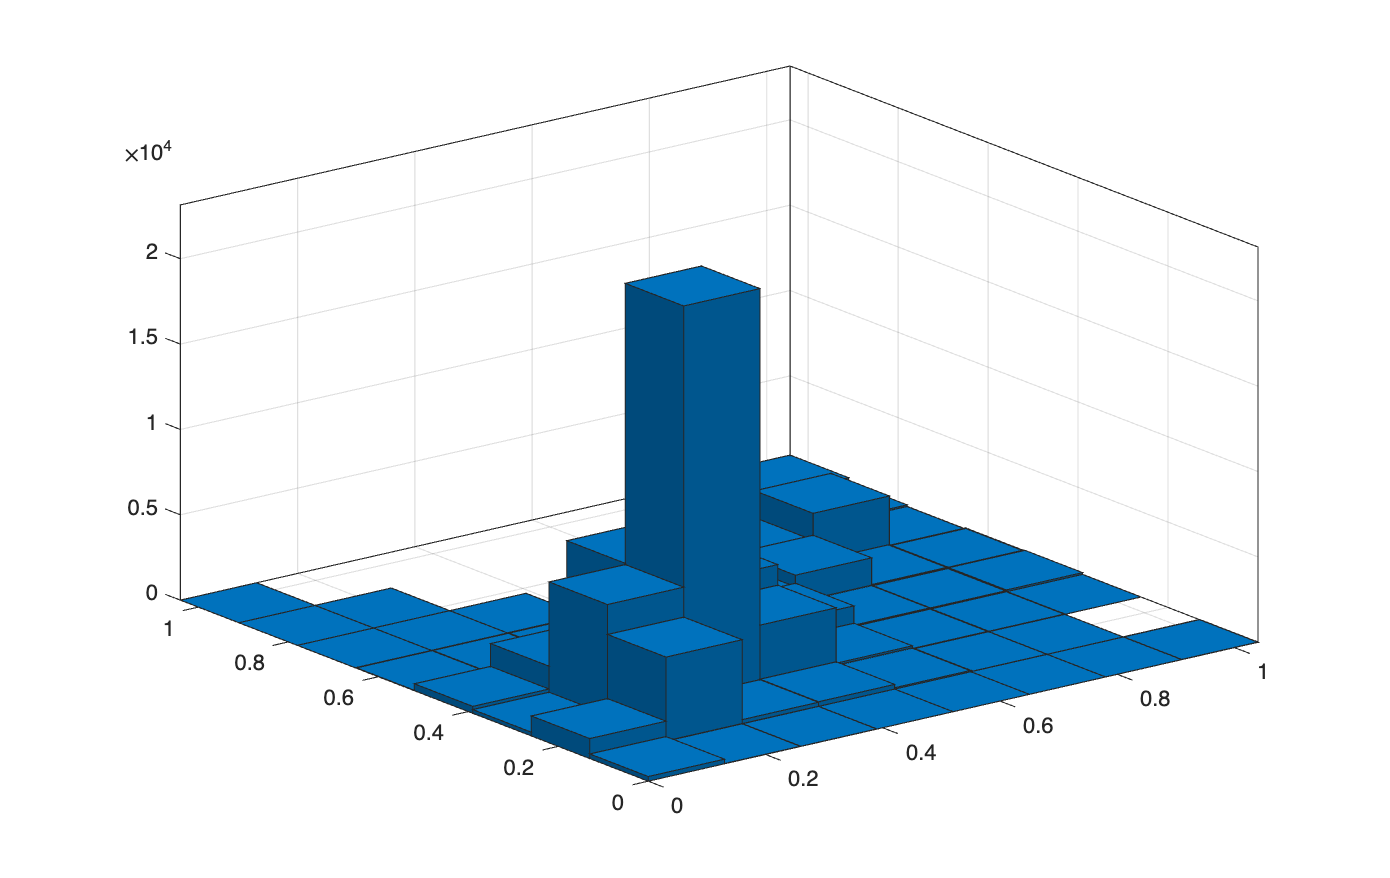

h2 = h2./sum(h2);
h3 = Calcular_Histograma_rg(im3).Values;

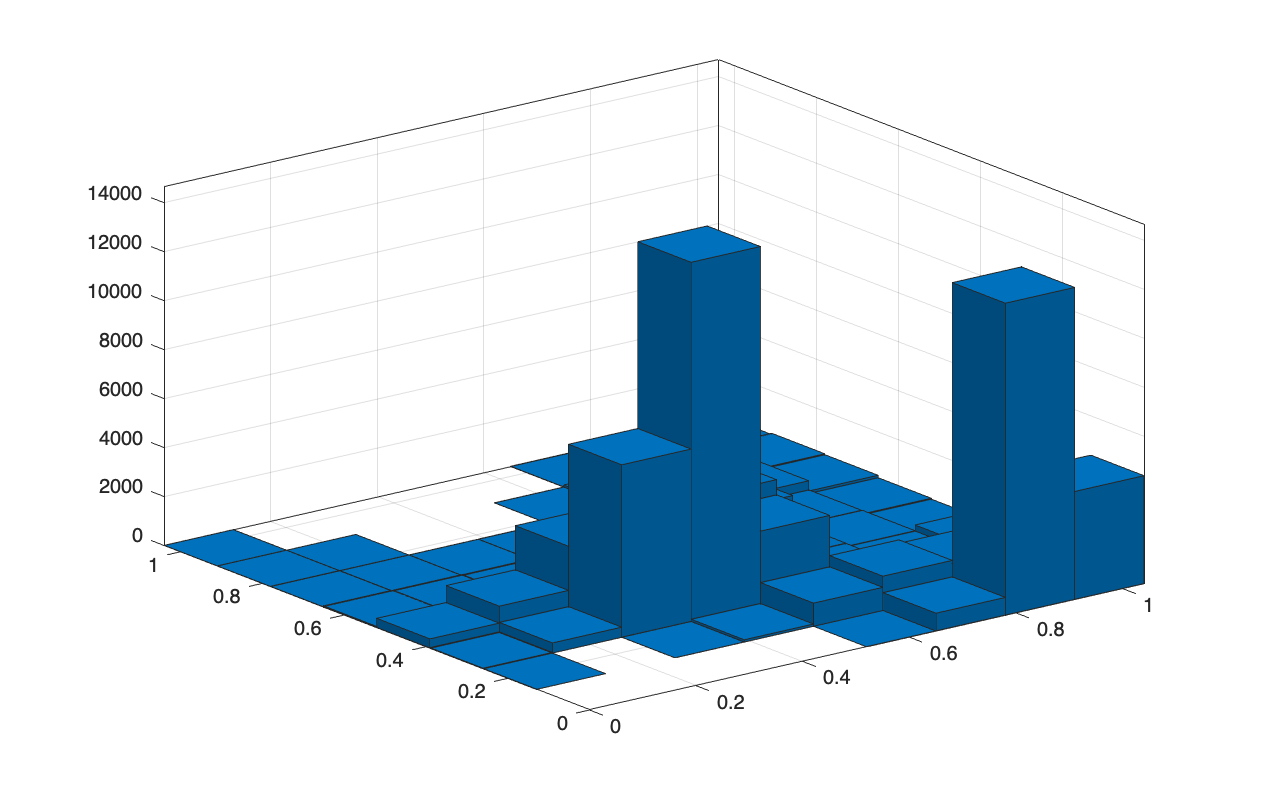

h3 = h3./sum(h3);
h4 = Calcular_Histograma_rg(im4).Values;

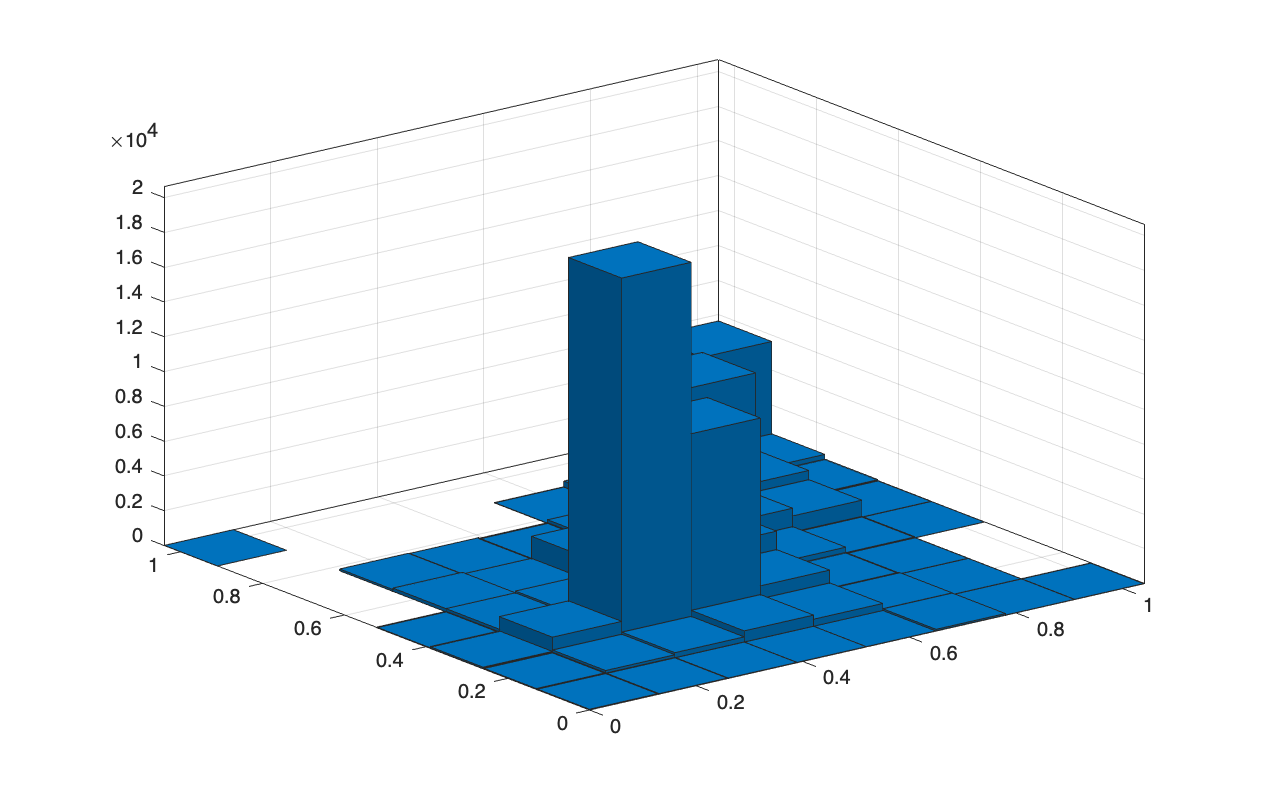

h4 = h4./sum(h4);
h5 = Calcular_Histograma_rg(im5).Values;

h5 = h5./sum(h5);

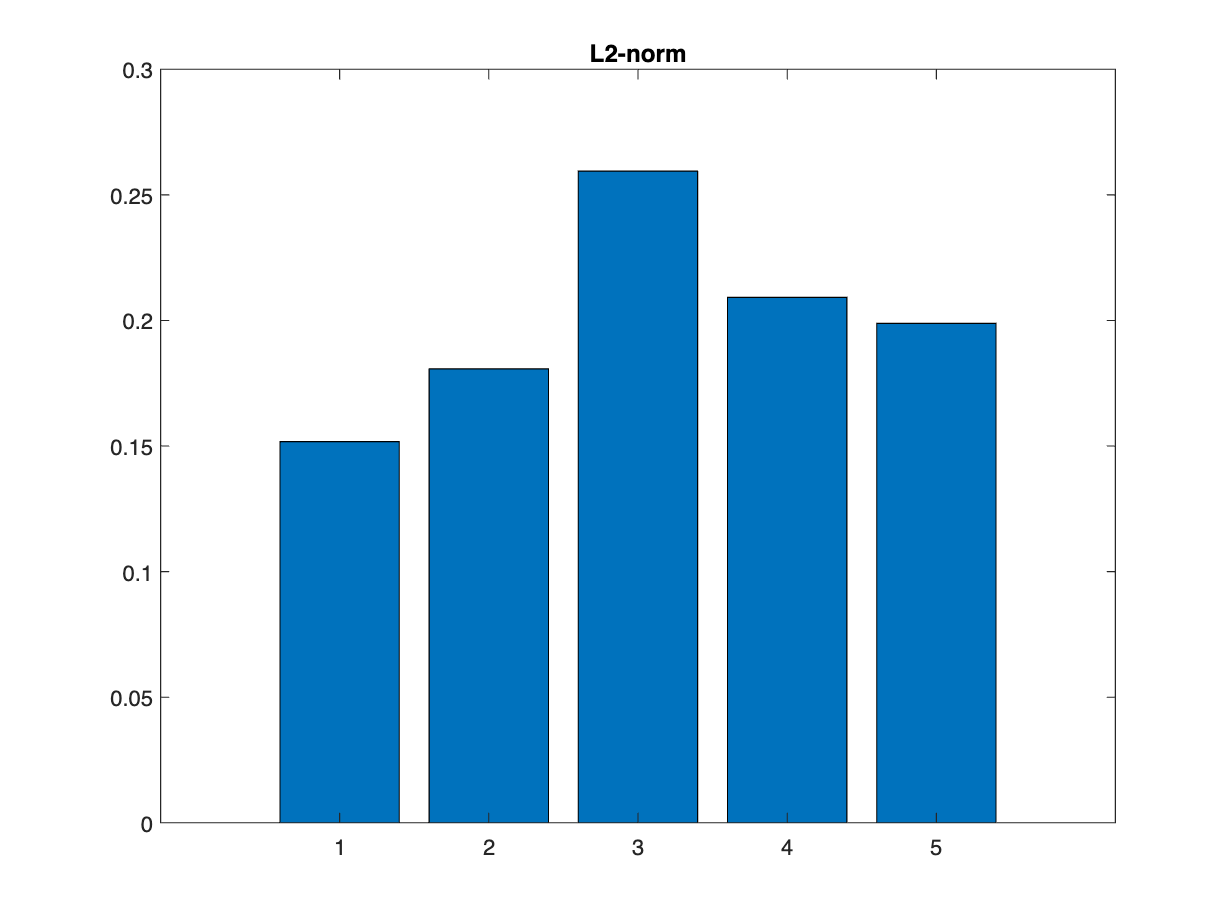

minVal = 0.1518

minPos = 1

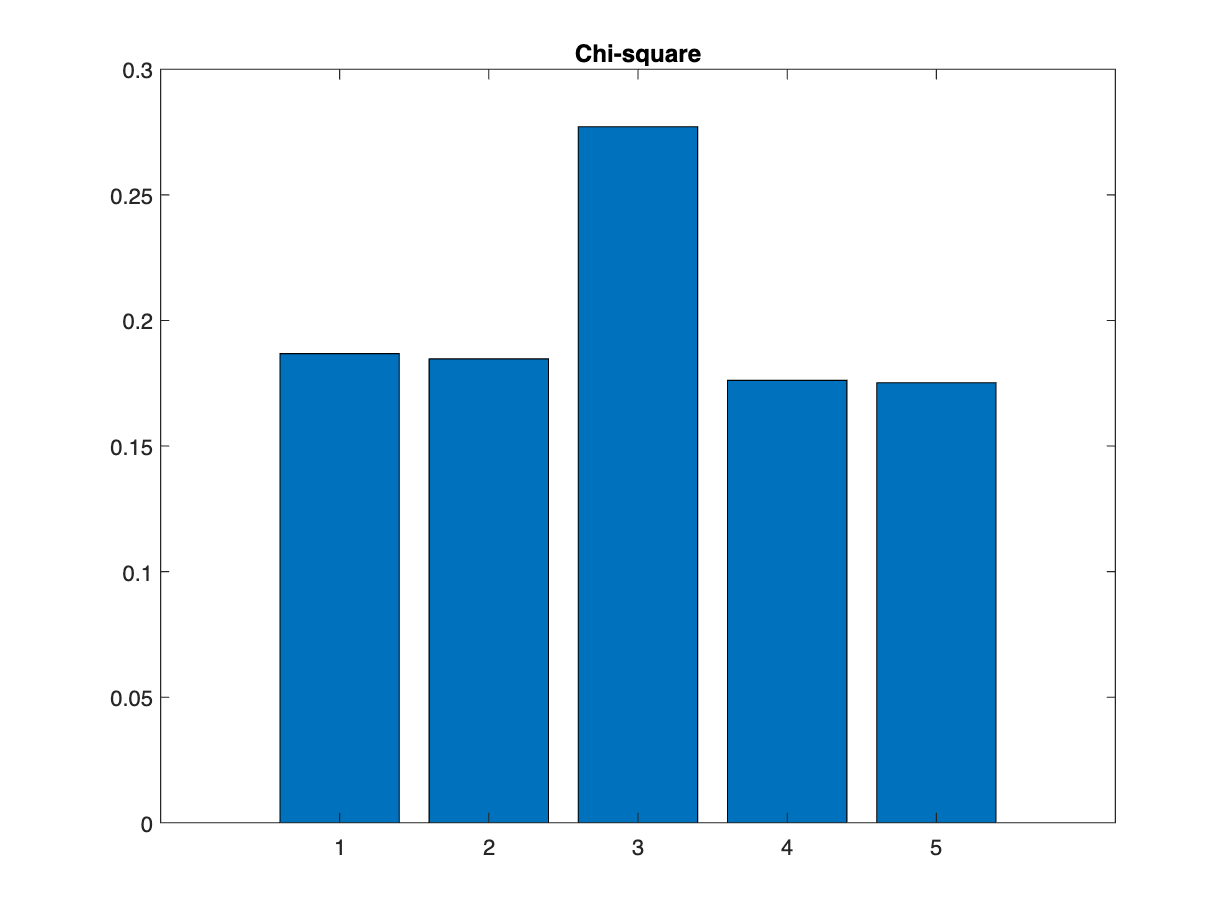

minVal = 0.1752

minPos = 5

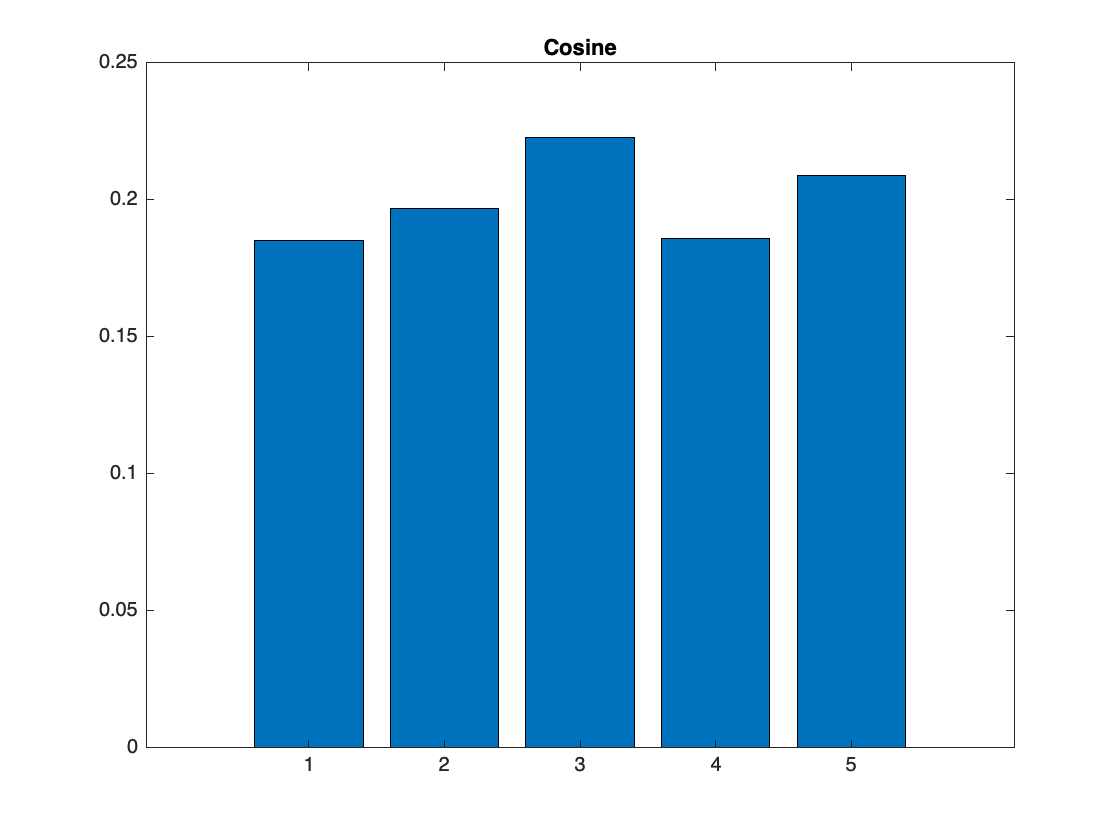

minVal = 0.1853

minPos = 1

% 3r pas: calcular la similitud basant-se en els histogrames
% metodes emprats: l2 norm, chi-square, cosine
L = ["L2-norm" "Chi-square" "Cosine"];
for method=1:3
    S(1) = Calcular_Similitud(h, h1, method);
    S(2) = Calcular_Similitud(h, h2, method);
    S(3) = Calcular_Similitud(h, h3, method);
    S(4) = Calcular_Similitud(h, h4, method);
    S(5) = Calcular_Similitud(h, h5, method);
    total = sum(S);
    S(1) = S(1)/total;
    S(2) = S(2)/total;
    S(3) = S(3)/total;
    S(4) = S(4)/total;
    S(5) = S(5)/total;
    figure
    bar(S)
    title(L(method))
    [minVal, minPos] = min(S)
end

#### Conclusions

El mètode que millor resultats ens ha donat de les 3 distàncies que hem fet servir ha sigut el càlcul amb la distància L2-norm. La distància Chi-square no dóna el matching esperat perquè les imatges tampoc són molt representatives, la samarreta del barça té colors lleugerament diferents degut a la il·luminació. També hem intentat fer un cropping al centre de la imatge, però els resultats seguien sent bastant dolents. 

Finalment, hem probat amb altres distancies com el cosine, mahalanobis o city block i ens dóna el matching bé, però amb resultats bastant semblants.

## Buscar vèrtexos: punts on es troben dos arestes (punts que tenen dos derivades)

function Dibuixar_Rectangle(im, pos_block)
    col = ceil(pos_block/14);
    fil = mod(pos_block, 14);
    X = 16 * col + 8;
    Y = 16 * fil + 8;
    rect = [X-24, Y-24, 48, 48];
    imshow(im);
    drawrectangle('Position', rect);
end


function [h] = Calcular_Histograma_rg(I)
    % Color normalization
    r = I(:,:,1);
    g = I(:,:,2);
    b = I(:,:,3);
    i = double(r + g + b);
    r = double(r)./i;
    g = double(g)./i;
    h = histogram2(r,g,8);
end

function [Sim] = Calcular_Similitud(h,h2,op)
    if op == 1
        % L2 distance
        Sim = norm(h - h2, 2);
    elseif op == 2
        % Chi-square
        Sim = sum(sum(((h - h2).^2) ./ (h + h2 + 0.000001)));
    else
        % Cosine Distance
        Sim = sum(sum(pdist2(h, h2, 'cosine')));
    end
end